# Wrapper Script

clear all;
close all;
clc;

## Inputs

T_se_int = [0 0 1 323.6; -1 0 0 -335.6; 0 -1 0 237; 0 0 0 1];
T_sc_int = [1 0 0 450; 0 1 0 -300; 0 0 1 0; 0 0 0 1];
T_sc_fin = [0 -1 0 0; 1 0 0 100; 0 0 1 0; 0 0 0 1];
T_ce_grp = [1 0 0 0; 0 1 0 0; 0 0 1 10; 0 0 0 1];
T_ce_stf = [1 0 0 0; 0 1 0 0; 0 0 1 50; 0 0 0 1];
Kp = zeros(6);
Ki = zeros(6);
dt = 0.01;

## Setup

% Tolerances and Constraints
eomg = 0.001;
ev = 0.1;
V_max = 40000000;


% Screw Axes and Zero Position Matrix
w1 = [0;0;1];
w2 = [0;1;0];
w3 = w2;
w4 = w2;
w5 = -w1;
w6 = w2;

q1 = [0;-300;88];
q2 = q1+[0;0;152];
q3 = q2+[244;120;0];
q4 = q3+[213;-93;0];
q5 = q4+[0;104; 0];
q6 = q5+[0;0;-85];

S1 = S_from_wq(w1,q1);
S2 = S_from_wq(w2,q2);
S3 = S_from_wq(w3,q3);
S4 = S_from_wq(w4,q4);
S5 = S_from_wq(w5,q5);
S6 = S_from_wq(w6,q6);

Slist = [S1 S2 S3 S4 S5 S6];
d = 155;
M = [1 0 0 457;0 1 0 -77+d;0 0 1 155;0 0 0 1];

B1 = StoB(S1,M);
B2 = StoB(S2,M);
B3 = StoB(S3,M);
B4 = StoB(S4,M);
B5 = StoB(S5,M);
B6 = StoB(S6,M);
Blist = [B1 B2 B3 B4 B5 B6];

% Initial Thetalist
thetalist = [ 0; 0; 0; 0; 0; 0];

## Trajectory

Trajectory = TrajectoryGenerator(T_se_int,T_sc_int,T_sc_fin,T_ce_grp,T_ce_stf,0.01);

## Iterations

T_se_r = Trajectory(1,:);
[T_se_d, eeo ]= invMatparse(T_se_r);
thetalist = IKinBody(Blist,M, T_se_d, thetalist,eomg, ev);
thetaArray(1,:) = [thetalist' eeo];
newthetalist = thetalist;
for i = 1:length(Trajectory)-1

    T_se_r = Trajectory(i,:);
    T_se_next_r = Trajectory(i+1,:);
    [T_se_d, eeo ]= invMatparse(T_se_r);
    T_se_d_next = invMatparse(T_se_next_r);
    T_se = T_se_d;
    twist = FeedbackControl(T_se,T_se_d,T_se_d_next,Kp,Ki,dt);
    thetalist = IKinBody(Blist,M, T_se_d, newthetalist,eomg, ev);
    %thetalist = jointLimits(thetalist, newthetalist);
    Jb = JacobianBody(Blist,thetalist);
    A(i,:) = thetalist;
    invJb = PinvJacobian(Jb);
    V_list = invJb*twist;
    newthetalist = NextState(thetalist,V_list, dt, V_max);
    Statelist(i+1,:) = [newthetalist' eeo];

end

## Output

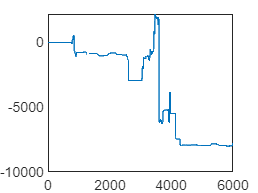


close all;
plot(1:6001,A(:,1))
hold on

%plot(1:1202,Statelist(:,2))
%plot(1:1202,Statelist(:,3))
%plot(1:1202,Statelist(:,4))
%plot(1:1202,Statelist(:,5))

csvwrite("Statelist.csv",Statelist)
